
I = (imread('Capture3.PNG'));

%I=rgb2gray(I);
[r,c,k]=size(I);
rChannel=I(:,:,1);
gChannel=I(:,:,2);
bChannel=I(:,:,3);
rArray=rChannel(:);
gArray=gChannel(:);
bArray=bChannel(:);

minArray=zeros(size(rArray));
for i=1:size(rArray)
   minArray(i)=min([rArray(i),gArray(i),bArray(i)]);
end
B=reshape(minArray,[136,135]);
imshow(B);

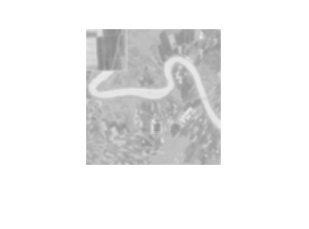


fun=@(x) 1-(sqrt(sum(x(:).^2))/(96*3*3));
T = nlfilter(B,[3 3],fun);
imshow(T);

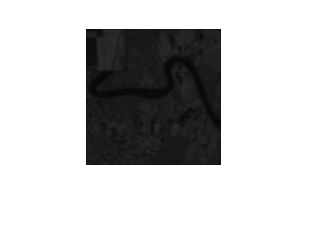


fun2=@(x) 0.3765*(1-(x));
TT=nlfilter(T,[1 1],fun2);
imshow(TT);

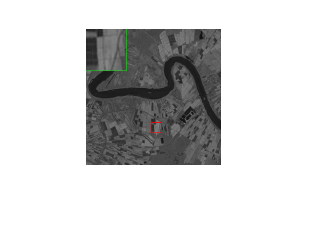

%TT=im2double(TT);


r=im2double(rChannel)-im2double(TT);
Jr=im2double(r)./im2double(T);
g=im2double(gChannel)-im2double(TT);
Jg=im2double(g)./im2double(T);
b=im2double(bChannel)-im2double(TT);
Jb=im2double(b)./im2double(T);
%Final(:,:,1)=Jr;
%Final(:,:,2)=Jg;
%Final(:,:,3)=Jb;
%imshow(Final)
imshow(I)

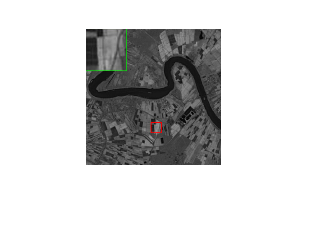

%imshow(Jr)
rgbImage = cat(3, Jr,Jg,Jb);
imshow(rgbImage)

rgbImageGray=rgb2gray(rgbImage);
H=entropy(rgbImageGray)

H = 6.7285

HFilter=[0 0 0;0 1 -1;0 0 0];
HFilterImage=imfilter(rgbImageGray,HFilter);
VFilter=[0 -1 0;0 1 0;0 0 0];
VFilterImage=imfilter(rgbImageGray,VFilter);
HFilterImage=HFilterImage.^2;
VFilterImage=VFilterImage.^2;
HV=HFilterImage+VFilterImage;
HV=HV.^0.5;
S=sum(HV(:));
S=S/(136*135)

S = 0.0702

DeltaRG=Jr-Jg;
DeltaYB=((Jr+Jg).*0.5)-Jb;
MeanRG=mean(DeltaRG(:));
MeanYB=mean(DeltaYB(:));
SdRG=std(DeltaRG(:));
SdYB=std(DeltaYB(:));
C=sqrt((SdRG^2)+(SdYB^2));
C=C+0.3*sqrt((MeanRG^2)+(MeanYB^2))

C = 0.0654